clear all; clc; close all;

% Apartado 1 y 2
A = [-6     4     0     2      0
      2     0     0    -2      0
      1     0    -1     0      1 
     -4     4     0     0      0
      6     0     1     0     -7];


% Apartado 3
[vA, lA] = eig(A)

vA =    -0.0000   -0.4189    0.3795   -0.3323   -0.0000
   -0.0000   -0.0000    0.1265   -0.3323   -0.0000
    0.1602    0.3770   -0.6957   -0.7200    0.9871
   -0.0000   -0.4189    0.5060   -0.3323   -0.0000
   -0.9871   -0.7121    0.3162   -0.3877    0.1602


lA =    -7.1623         0         0         0         0
         0   -4.0000         0         0         0
         0         0   -2.0000         0         0
         0         0         0   -0.0000         0
         0         0         0         0   -0.8377


Vemos que todos los autovaloes son distintos. Todos tienen parte real negativa menos un autovalor que es exactamente cero. Mirando (5.18) en el manual podemos concluir que el único autovector (multiplicado por una constante) que "sobrevive" es el correspondiente al autovalor cero. Estudiando ese autovector podemos responder a las preguntas:

a) Los señores 1, 2 y 4 terminan con las mismas opiniones

b) Todos terminarán con opinión del mismo signo, positiva o negativa dependiendo de las condiciones iniciales que determinan la constante c en (5.18).

c) El señor 3 siempre terminará con una opinión más radical, casi el doble de fuerte que el resto. El señor 5 siempre termina con una opinión cercana a 1, 2 y 4.

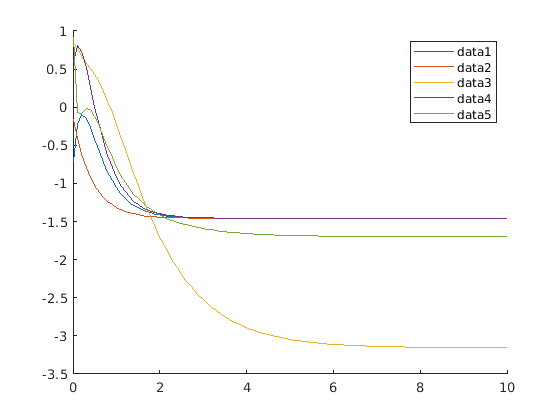

% Apartado 4 para comprobar numéricamente el
% apartado 3

% Puedes integrar por Euler "a mano" o usar ode45.

tf = 10;
deltaT = 0.1;
t = 0:deltaT:tf;

x = -1 + 2*rand(5,1);
log_x = zeros(length(t), 5);

for i = 1:length(t)

log_x(i,:) = x';    

x_dot = A*x;
x = x + x_dot*deltaT;
    
end

figure(1)
hold on
for j = 1:5
    plot(t, log_x(:,j));
end
legend()

% Apartado 5
[vAt, lAt] = eig(A')

vAt =    -0.8018   -0.7071    0.5774    0.6256   -0.8512
    0.2673    0.0000    0.5774    0.3343    0.2964
         0         0         0   -0.1122   -0.0467
    0.5345    0.7071   -0.5774   -0.6956    0.3205
         0         0         0   -0.0182    0.2875


lAt =    -4.0000         0         0         0         0
         0   -2.0000         0         0         0
         0         0    0.0000         0         0
         0         0         0   -0.8377         0
         0         0         0         0   -7.1623


Observando los autovectores de A traspuesto podemos estudiar en donde poner las entradas (a quien mostrar la campaña) para determinar la controlabilidad del sistema (llevar las opiniones a cualquier valor que nos interese). Vamos a explotar los Teoremas 6.2.3 y 6.2.4.

Tenemos que enseñar la misma campaña (u(t) tiene dimension 1) a dos personas. Por lo que B tendrá una columna con dos unos, y tres ceros.

a) Estudiamos las columnas de vAt (autovectores de A traspuesto). Vemos que en la segunda columna si enseñamos la misma campaña a los señores 1 y 4, perdemos controlabilidad. En la tercera columna la misma capaña a los señores 1 y 4, o 2 y 4 perdemos controlabilidad. También viendo las tres primeras columnas, vemos que escoger al señor 3 y 5 es muy mala idea. Si vemos la segunda columna, escoger al 2 y al 5, o al 2 y el 3 tampoco es buena idea.

B1 = [1;0;0;1;0]; % Enseñamos la campaña a 1 y 4
B2 = [0;1;0;1;0]; % Enseñamos la campaña a 2 y 4
B1'*vAt % Dos autovectores en el kernel de B1'

ans =    -0.2673   -0.0000    0.0000   -0.0700   -0.5308


B2'*vAt % Un autovector en el kernel de B2'

ans =     0.8018    0.7071    0.0000   -0.3614    0.6169


b) Escoge dos personas de tal manera que ningún elemento B'*vAt esté "muy cerca" de cero. Si no, aunque sea el sistema controlable, será poco efectiva.

B = [1;0;0;0;1] % Por ejemplo al 1 y al 5

B =      1
     0
     0
     0
     1


B'*vAt

ans =    -0.8018   -0.7071    0.5774    0.6074   -0.5637


Para llevar las opiniones en un tiempo finito a donde queramos, hacemos uso de "Atención 6.2.1" en el manual.

t1 = 10; % Tiempo final
dt = 0.001; % Paso de tiempo para la integración por Euler
Wr = gramfun(t1,A,B,dt); % Calculo numérico del Gramiano
x1 = 10*ones(5,1); % Estado final
x = [0;0;0;0;0]; % Estado inicial
eta = inv(Wr)*(x1-x); % Tenemos la suerte de que Wr es positiva definida en este caso

log_t = 0:dt:t1;
log_u = zeros(length(log_t),1);
log_x = zeros(length(log_t),5);

for i  = 1:length(log_t)
    t = log_t(i);
    
    u = B'*expm(A'*(t1-t))*eta;
    
    dx = A*x + B*u;
    x = x + dx*dt;
    
    log_u(i,:) = u;
    log_x(i,:) = x;
end

% Comprobamos que llegamos a x1 en el tiempo t1.
x 

x =    10.0019
   10.0005
   10.0069
   10.0024
   10.0065


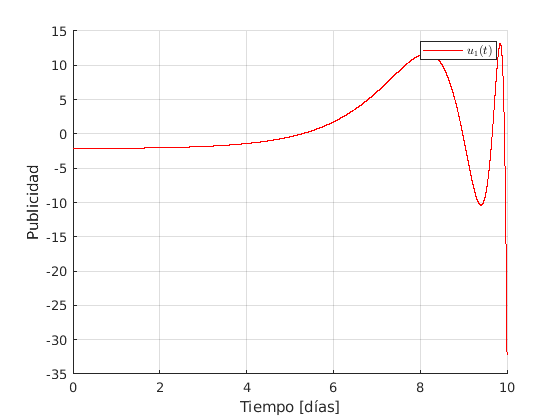


figure(10)
hold on
plot(log_t,log_u(:,1),'r')
grid on
legend('$u_1(t)$','Interpreter','latex')
xlabel('Tiempo [días]')
ylabel('Publicidad')

Vemos que para alcanzar una opinión positiva de valor 10 en todo el mundo, durante los primeros días tenemos que hablar negativamente.

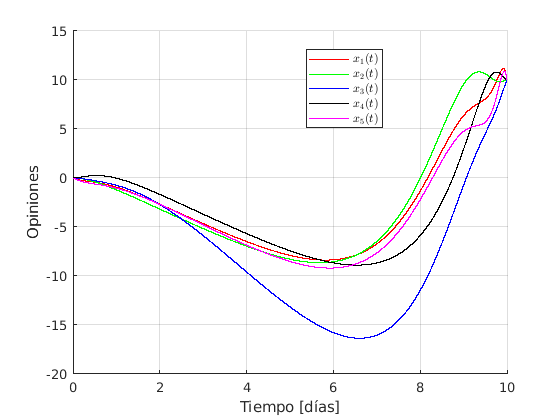


figure(11)
hold on
plot(log_t,log_x(:,1),'r')
plot(log_t,log_x(:,2),'g')
plot(log_t,log_x(:,3),'b')
plot(log_t,log_x(:,4),'k')
plot(log_t,log_x(:,5),'m')
grid on
legend('$x_1(t)$','$x_2(t)$','$x_3(t)$','$x_4(t)$','$x_5(t)$','Interpreter','latex', 'Location', "best")
xlabel('Tiempo [días]')
ylabel('Opiniones')

% Apartado 7
% Problema de observabilidad. Teorema 6.4.2

Si miramos las columnas de vA, vemos que con encuestar al señor 3 o 5 vale.

vA

vA =    -0.0000   -0.4189    0.3795   -0.3323   -0.0000
   -0.0000   -0.0000    0.1265   -0.3323   -0.0000
    0.1602    0.3770   -0.6957   -0.7200    0.9871
   -0.0000   -0.4189    0.5060   -0.3323   -0.0000
   -0.9871   -0.7121    0.3162   -0.3877    0.1602



C1 = [0 0 1 0 0];
C2 = [0 0 0 0 1];

C1*vA

ans =     0.1602    0.3770   -0.6957   -0.7200    0.9871


C2*vA

ans =    -0.9871   -0.7121    0.3162   -0.3877    0.1602


Vamos a diseñar el estimador (6.56) en el manual. Primero la ganancia L, y el resto ya lo tenemos, ya que la A, B, C y D del estimador son copias del sistema dinámico. Me quedo encuestando solo al señor 3.

L = (place(A',C1',[-4, -6, -8, -10, -11]))' % Sistema dual

L =   124.5315
  176.8951
   25.0000
   98.3497
   80.4685


Ahora copiamos y pegamos la misma simulación de arriba, pero incluyendo al estimador

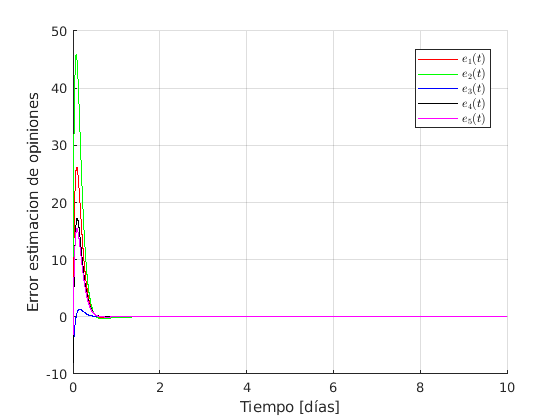

t1 = 10; % Tiempo final
dt = 0.001; % Paso de tiempo para la integración por Euler
Wr = gramfun(t1,A,B,dt); % Calculo numérico del Gramiano
x1 = 10*ones(5,1); % Estado final
x = [0;0;0;0;0]; % Estado inicial
eta = inv(Wr)*(x1-x); % Tenemos la suerte de que Wr es positiva definida en este caso

log_t = 0:dt:t1;
log_u = zeros(length(log_t),1);
log_x = zeros(length(log_t),5);
log_xhat = zeros(length(log_t),5);

Ahat = A;
Bhat = B;
Chat = C1;
xhat = -10 + 20*rand(5,1);

for i  = 1:length(log_t)
    t = log_t(i);
    u = B'*expm(A'*(t1-t))*eta;
   
    % Dinamica opiniones
    dx = A*x +B*u;
    x = x+dx*dt;
    y = C1*x; % La encuesta el señor 3
    
    % Dinamica del estimador
    yhat = Chat*xhat;
    dxhat = A*xhat + B*u -L*(yhat - y);
    xhat = xhat + dxhat*dt;
        
    log_u(i,:) = u;
    log_x(i,:) = x;
    log_xhat(i,:) = xhat;
end


figure(21)
hold on
plot(log_t,log_x(:,1)-log_xhat(:,1),'r')
plot(log_t,log_x(:,2)-log_xhat(:,2),'g')
plot(log_t,log_x(:,3)-log_xhat(:,3),'b')
plot(log_t,log_x(:,4)-log_xhat(:,4),'k')
plot(log_t,log_x(:,5)-log_xhat(:,5),'m')
grid on
legend('$e_1(t)$','$e_2(t)$','$e_3(t)$','$e_4(t)$','$e_5(t)$','Interpreter','latex', 'Location', "best")
xlabel('Tiempo [días]')
ylabel('Error estimacion de opiniones')

Vemos que todos los errores de estimación van a cero. Es decir, podemos conocer todas las opiniones de todo el mundo únicamente encuestando al señor 3 y sabiendo la dinámica de la red social.

% Miramos que en efecto, las opiniones han llegado todas a 10
x

x =    10.0019
   10.0005
   10.0069
   10.0024
   10.0065


xhat

xhat =    10.0061
   10.0029
   10.0188
   10.0075
   10.0127


% Apartado 8, controlador LQR

Diseñamos la Q y R para LQR

rho = 1;
% La norma de u no puede ser mayor que 2
% Para los estados menor que 500
Qbar = 1/(300*300)*eye(5);
Rbar = 1/(2*2);

G = eye(5); % Atencion, el LQR lo quiero para los 4 estados
H = zeros(5,1); % Las mismas dimensiones que B porque G tiene las mismas dimensiones que A
Q = G'*Qbar*G;
R = H'*Qbar*H + rho*Rbar;
N = G'*Qbar*H;

K = lqr(A,B,Q,R,N)

K =     0.0198    0.0199    0.0000   -0.0198    0.0000


Ahora simulamos, podemos copiar y pegar la simulación anterior para reutilizar el estimador.

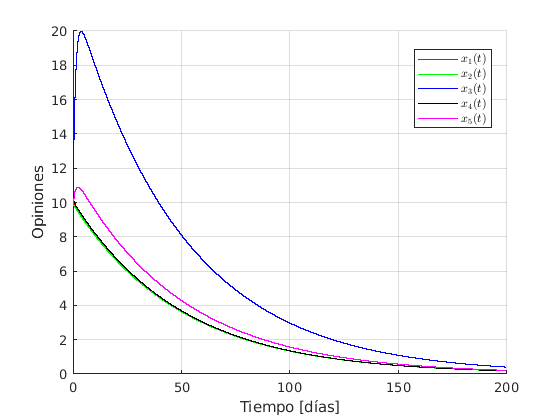

t1 = 200; % Tiempo final
dt = 0.001; % Paso de tiempo para la integración por Euler
x = [10;10;10;10;10]; % Estado inicial

log_t = 0:dt:t1;
log_u = zeros(length(log_t),1);
log_x = zeros(length(log_t),5);
log_xhat = zeros(length(log_t),5);

Ahat = A;
Bhat = B;
Chat = C1;
xhat = -10 + 20*rand(5,1);

for i  = 1:length(log_t)
    t = log_t(i);
    u = -K*xhat; % Controlador LQR ahora
   
    % Dinamica opiniones
    dx = A*x + B*u;
    x = x + dx*dt;
    y = C1*x; % La encuesta el señor 3
    
    % Dinamica del estimador
    yhat = Chat*xhat;
    dxhat = A*xhat + B*u -L*(yhat - y);
    xhat = xhat + dxhat*dt;
        
    log_u(i,:) = u;
    log_x(i,:) = x;
    log_xhat(i,:) = xhat;
end

figure(31)
hold on
plot(log_t,log_x(:,1),'r')
plot(log_t,log_x(:,2),'g')
plot(log_t,log_x(:,3),'b')
plot(log_t,log_x(:,4),'k')
plot(log_t,log_x(:,5),'m')
grid on
legend('$x_1(t)$','$x_2(t)$','$x_3(t)$','$x_4(t)$','$x_5(t)$','Interpreter','latex', 'Location', "best")
xlabel('Tiempo [días]')
ylabel('Opiniones')

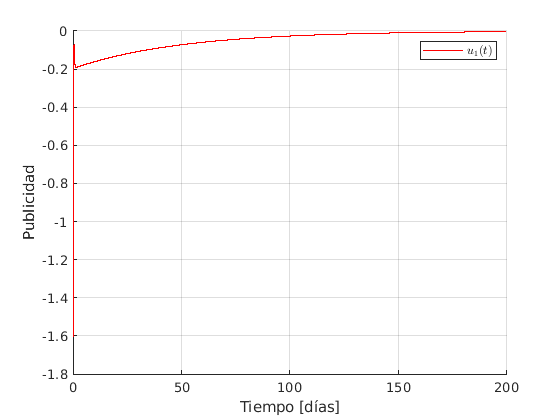


figure(32)
hold on
plot(log_t,log_u(:,1),'r')
grid on
legend('$u_1(t)$','Interpreter','latex')
xlabel('Tiempo [días]')
ylabel('Publicidad')

Vemos que en efecto, la entrada no supera el valor de 2 en valor absoluto. 

Función para calcular numéricamente el Gramian de alcanzabilidad 

function wr = gramfun(t1,A,B,dt)
wr = zeros(size(A));

for t=0:dt:t1
    wr = wr + expm(A*(t1-t))*B*B'*[expm(A*(t1-t))]'*dt;
end

end